% calculating rref of matrix
A = [1 0 1 1 0 0; 0 1 -3 -1 1 1; 0 0 0 -1 -2 -1]

A =      1     0     1     1     0     0
     0     1    -3    -1     1     1
     0     0     0    -1    -2    -1


rref(A)

ans =      1     0     1     0    -2    -1
     0     1    -3     0     3     2
     0     0     0     1     2     1



% graviational acceleration
g = 9.81; 
% densities with corn syrup first and shampoo second
p = [1427.1 1427.1 1427.1 1427.1 1427.1 1018.0 1018.0 1018.0 1018.0 1018.0];
% viscosities with shampoo first and corn syrup second
mu = [5 5 5 5 5 20 20 20 20 20];
% masses of marbles 1-5 twice
m = [0.003 0.005 0.013 0.022 0.054 0.003 0.005 0.013 0.022 0.054];
% radii of marbles 1-5 twice
r = [0.007 0.008 0.011 0.013 0.0175 0.007 0.008 0.011 0.013 0.0175];
%velocities with corn syrup first and shampoo second
v = [0.026 0.030 0.046 0.070 0.076 0.009 0.010 0.016 0.019 0.021];

% pi1, pi2, pi3 values
pi1 = r.^3 .* p ./ (m) 

pi1 =     0.1632    0.1461    0.1461    0.1425    0.1416    0.1164    0.1042    0.1042    0.1017    0.1010


pi2 = (m.^2 .* g) ./ (r.^3 .* mu.^2)

pi2 =    10.2962   19.1602   49.8239   86.4459  213.5022    0.6435    1.1975    3.1140    5.4029   13.3439


pi3 = (v .^ 2) ./ (r .* g)

pi3 =     0.0098    0.0115    0.0196    0.0384    0.0336    0.0012    0.0013    0.0024    0.0028    0.0026


% Fit
F=[ones(size(pi3))' pi1' pi2']

F =     1.0000    0.1632   10.2962
    1.0000    0.1461   19.1602
    1.0000    0.1461   49.8239
    1.0000    0.1425   86.4459
    1.0000    0.1416  213.5022
    1.0000    0.1164    0.6435
    1.0000    0.1042    1.1975
    1.0000    0.1042    3.1140
    1.0000    0.1017    5.4029
    1.0000    0.1010   13.3439


phi_vals=F\pi3'

phi_vals =    -0.0197
    0.2072
    0.0001


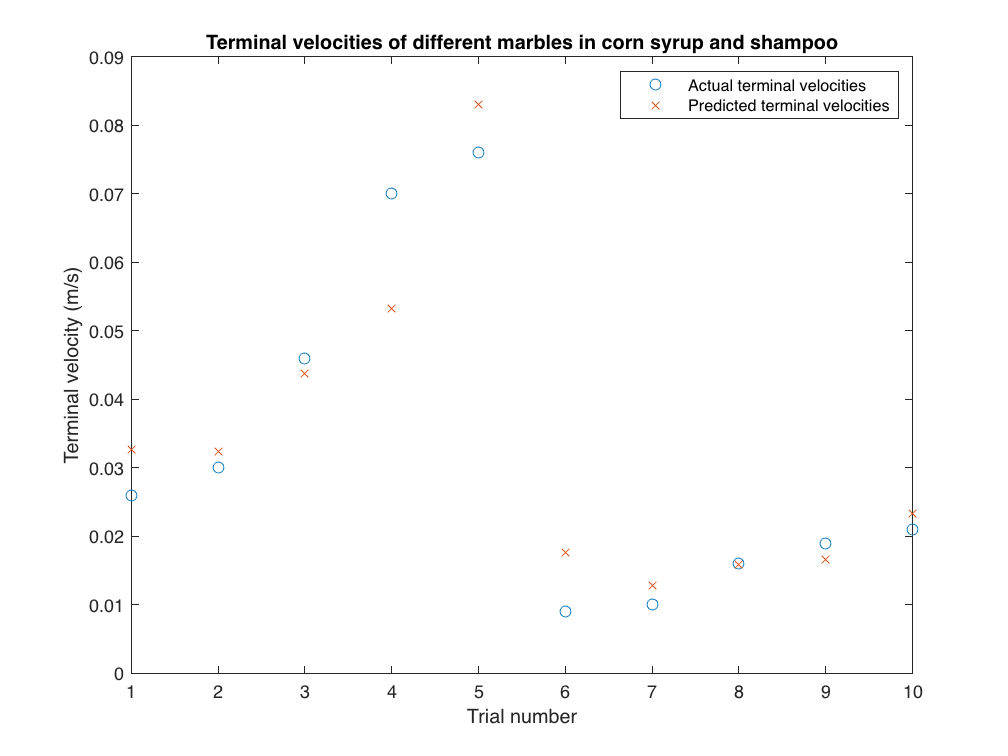

x = 1:1:10;
pi3 = phi_vals(1) + phi_vals(2) .* pi1 + phi_vals(3) .* pi2;
v_t = sqrt(r .* g .* pi3);
% plotting exact values of v
plot(x, v, 'o')
hold on
% plotting predicted values of v
plot(x, v_t, 'x')
hold off
title("Terminal velocities of different marbles in corn syrup and shampoo");
ylabel("Terminal velocity (m/s)");
xlabel("Trial number");
legend('Actual terminal velocities', 'Predicted terminal velocities');

% SSR of fit
E = sum((v - v_t).^2)

E = 4.8053e-04

s = sqrt(E ./ (10 - 3))

s = 0.0083